## Exercises L3 - Unit Quaternions

## Wrap-Up

#### MATLAB/RTB Functions

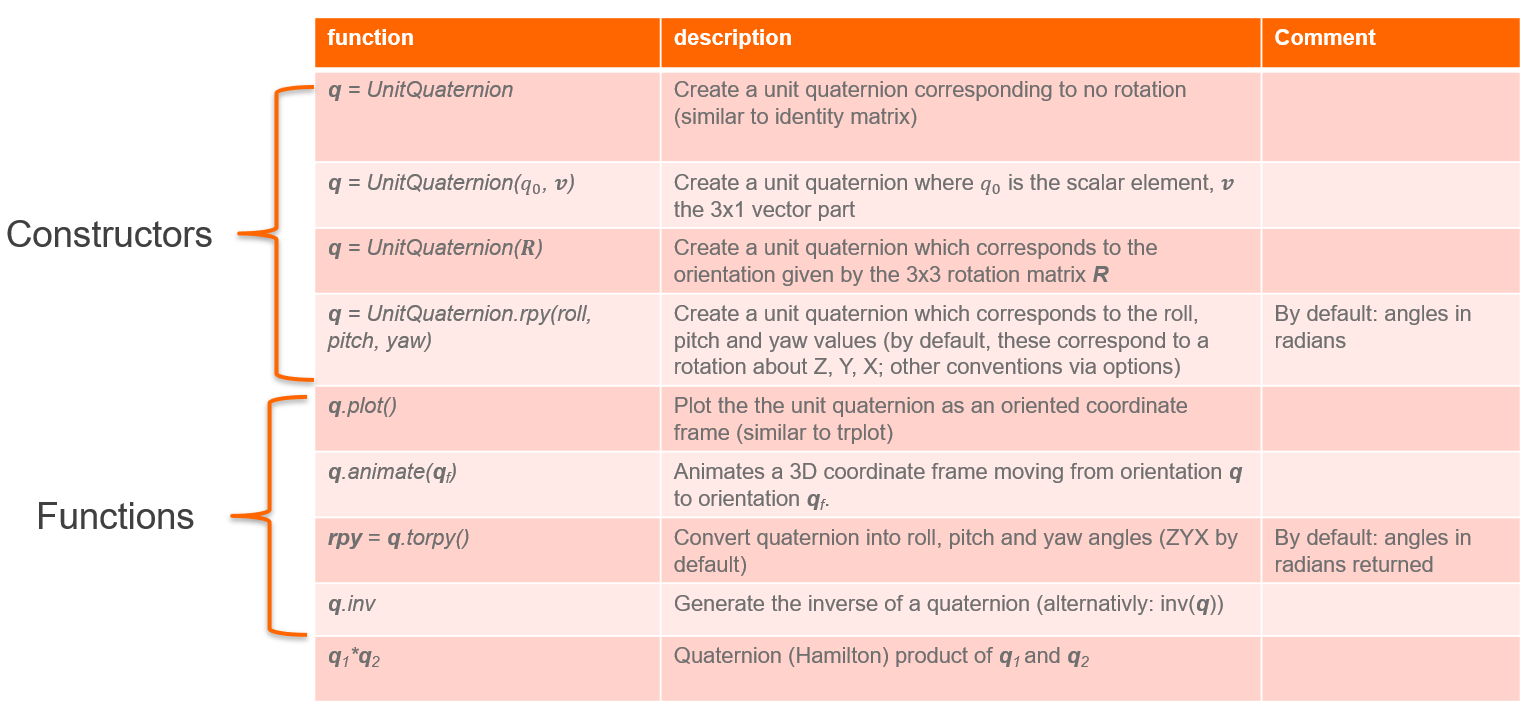

### Exercise 3.1

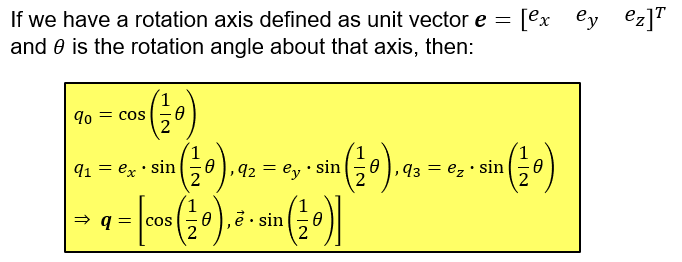

- Use the equations above to generate a quaternion which represents a rotation of 90° about the x-axis

- Determine the length of the quaternion and verify that it is a unit quaternion

- Convert the quaternion from the previous exercise to a unit quaternion object using the RTB class constructor UnitQuaternion(q0,**v**) (see table at the top)

- plot the quaternion as a frame using the class method plot (see table at the top) and compare the local axes to the global axes to verify the rotation

clear all; close all;
disp("Exercise 3.1");
% 1. Use the equations above to generate a quaternion which represents a rotation of 90° about the x-axis
 % unit vector representing x-axis
 e = ...   
 % rotation angle in rad
 theta = ... 
 % row vector with 4 elements
 q = ...  

% 2. Determine the length of the quaternion and verify that it is a unit quaternion
 q_norm = ...  

% 3. Convert the quaternion from the previous exercise to a unit quaternion object using the RTB class constructor UnitQuaternion(q0,v) 
 q_obj = ...

% 4. plot the quaternion as a frame using the class method plot (see table at the top)
 ...
 view(3);


### Exercise 3.2

- Use the RTB function *UnitQuaternion* to generate a unit quaternion ${\mathit{\mathbf{q}}}_0$ representing "no rotation"

- plot the quaternion as a frame using the *plot* method availabe in the UnitQuaternion class. Make sure that the frame is labled as {0} using the 'frame' option.

- Generate another unit quaternion ${\mathit{\mathbf{q}}}_1$ representig a rotation of roll = 30° regarding *x*, pitch = 45° regarding *y* and 90° regarding *z*-axis

- plot ${\mathit{\mathbf{q}}}_1$ as a frame into the same figure in green (use the 'Color' option) and name it {1}

- in the MATLAB command window: generate a new figure, set view(3) and use the *animate* method to show an animated transformation from frame {0} to {1}

- use the *rpy* method to convert ${\mathit{\mathbf{q}}}_1$ into roll, pitch, yaw euler angles and compare the result to the initial input angles (both in degrees). Verify the result.

clear; close all;
disp("Exercise 3.2");
%% 1. Use the RTB function UnitQuaternion to generate a unit quaternion representing no rotation 
 % q0 = ... 

 %% 2. plot the quaternion as a frame using the plot method availabe in the UnitQuaternion class. Make sure that the frame is labled as {0} using the 'frame' option.
 % ...

 %% 3. Generate another unit quaternion q1 representig a rotation of roll = 30° regarding x, pitch = 45° regarding y and 90° regarding z-axis
 % roll = ...; 
 % pitch = ...;
 % yaw = ...;
 % q1 = ...

%% 4. plot q1 as a frame into the same figure in green (use the 'Color' option) and name it {1}
 %% command for plotting into the same figure
 % ... 
 %% plot command
 % ...
 % view(3);

%% 5. in the MATLAB command window): generate a new figure, set view(3) and use the animate method to show an animated transformation from frame {0} to {1}
 %% (nothing to be written here --> move to matlab command window) 

%% 6. use the rpy method to convert into roll, pitch, yaw euler angles and compare the result to the initial input angles (both in degrees). Verify the result.
 % rpy = ...

### Exercise 3.3

- Generate ${\mathit{\mathbf{q}}}_1$ as in the previous exercise (or reuse it)

- "revert" the rotation represented by ${\mathit{\mathbf{q}}}_1$to gain the quaternion representing no rotation (recall compounding of quaternions by multiplication and the inverse operation)

disp("Exercise 3.3");
%% 1. Generate q1 as in the previous exercise (or reuse it)
 % q1 = ...; (or use the q1 from previous code)

%% 2. "revert" the rotation represented by q1 to gain the quaternion representing no rotation 
 % q1_inv = ...;
 % q0 = ...; % compound q1 and q1_inv
 % disp(q0);


### Exercise 3.4

- Generate ${\mathit{\mathbf{q}}}_1$ representig a rotation of roll = 30° regarding *x*, pitch = 90° regarding *y* (**gimbal lock condition**!) and 45° regarding *z*-axis

- Generate ${\mathit{\mathbf{q}}}_{\textrm{delta}}$ representig a rotation of roll = 45° regarding *x *(other angles 0)

- Compound orientation ${\mathit{\mathbf{q}}}_1$ and ${\mathit{\mathbf{q}}}_{\textrm{delta}}$ into ${\mathit{\mathbf{q}}}_2$

- Plot ${\mathit{\mathbf{q}}}_1$ and ${\mathit{\mathbf{q}}}_2$ as frames (different colors) and verify that the resulting orientation is as expected

- Convert ${\mathit{\mathbf{q}}}_2$ into euler angles. Which angles would you expect? Which did you get by conversion?

disp("Exercise 3.4");

%% 1. Generate  representig a rotation of roll = 30° regarding x, pitch = 90° regarding y (gimbal lock condition!) and 45° regarding z-axis
 % roll = ...;
 % pitch = ...;
 % yaw = ...;
 % q1 = ...;

%% 2. Generate q_delta representig a rotation of roll = 45° regarding x (other angles 0)
 % q_delta = ...;

%% 3. Compound orientation q1 and q_delta into q2
 % q2 = ...;

%% 4. Plot q1 and q2 as frames (different colors) and verify that the resulting orientation is as expected
 % figure;
 %% plot q1
 % ...
 % hold on;
 %% plot q2;
 % ...
 % view(3);
 % grid on;

%% 5. Convert q2 into euler angles. Which angles would you expect? Which did you get by conversion?
 % rpy = ...;
 % disp(rpy);